## Zadanie 7.1

value = 0.56532;
sign=1; %0-unsigned value, 1-signed value % sign
prec_i=1; %number of integer part bits (Nc) % one bit
prec_f=10; %number of fractional part bits (Nu) % eight bits
word = 1 + prec_i + prec_f; % whole word
o_fix = fi(value,sign,word,prec_f)

o_fix =     0.5654

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 10

bin(o_fix)

ans = '001001000011'

## Sprawdzenie dokładności

A = 0.32345;
B = -0.78743;
C = 0.56532;

A_fix = fi(A, 1, 12, 10);
bin(A_fix)

ans = '000101001011'

epsA = A - double(A_fix)

epsA = 2.0781e-04

B_fix = fi(B, 1, 12, 10);
epsB = B - double(B_fix)

epsB = -3.2062e-04


C_fix = fi(C, 1, 12, 10);
epsC = C - double(C_fix)

epsC = -1.0969e-04

AB = (A_fix + B_fix)

AB =    -0.4639

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 10

Y_fix = (A_fix + B_fix) * C_fix

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 25
        FractionLength: 20

Y_fix.bin

ans = '1111110111100110110101111'

Y = (A + B) * C;
Y_fix = (A_fix + B_fix) * C_fix;

epsY = Y - double(Y_fix);

res = zeros(1,16);
for prec_f=0:16
    A_fix = fi(A, 1, prec_f+2, prec_f);
    B_fix = fi(B, 1, prec_f+2, prec_f);    
    C_fix = fi(C, 1, prec_f+2, prec_f);
    sprintf("Zadana precyzja %d",prec_f)
    
    Y_fix = (A_fix + B_fix) * C_fix
    bin(Y_fix)
    res(prec_f+1) = abs(Y - double(Y_fix));
    sprintf("Wartośc błedu %f",double(res(prec_f+1)))
end

ans = "Zadana precyzja 0"

Y_fix =     -1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 5
        FractionLength: 0

ans = '11111'

ans = "Wartośc błedu 0.737703"

ans = "Zadana precyzja 1"

Y_fix =    -0.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 2

ans = '1111111'

ans = "Wartośc błedu 0.012297"

ans = "Zadana precyzja 2"

Y_fix =    -0.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 4

ans = '111111100'

ans = "Wartośc błedu 0.012297"

ans = "Zadana precyzja 3"

Y_fix =    -0.2344

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 6

ans = '11111110001'

ans = "Wartośc błedu 0.027922"

ans = "Zadana precyzja 4"

Y_fix =    -0.2812

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 8

ans = '1111110111000'

ans = "Wartośc błedu 0.018953"

ans = "Zadana precyzja 5"

Y_fix =    -0.2637

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 10

ans = '111111011110010'

ans = "Wartośc błedu 0.001375"

ans = "Zadana precyzja 6"

Y_fix =    -0.2549

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 17
        FractionLength: 12

ans = '11111101111101100'

ans = "Wartośc błedu 0.007414"

ans = "Zadana precyzja 7"

Y_fix =    -0.2637

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 14

ans = '1111110111100100000'

ans = "Wartośc błedu 0.001375"

ans = "Zadana precyzja 8"

Y_fix =    -0.2633

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 16

ans = '111111011110010011001'

ans = "Wartośc błedu 0.000993"

ans = "Zadana precyzja 9"

Y_fix =    -0.2613

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 23
        FractionLength: 18

ans = '11111101111010001110011'

ans = "Wartośc błedu 0.001017"

ans = "Zadana precyzja 10"

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 25
        FractionLength: 20

ans = '1111110111100110110101111'

ans = "Wartośc błedu 0.000013"

ans = "Zadana precyzja 11"

Y_fix =    -0.2626

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 27
        FractionLength: 22

ans = '111111011110011001000110110'

ans = "Wartośc błedu 0.000263"

ans = "Zadana precyzja 12"

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 29
        FractionLength: 24

ans = '11111101111001101101011110000'

ans = "Wartośc błedu 0.000013"

ans = "Zadana precyzja 13"

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 31
        FractionLength: 26

ans = '1111110111100110110100010000001'

ans = "Wartośc błedu 0.000001"

ans = "Zadana precyzja 14"

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 33
        FractionLength: 28

ans = '111111011110011011010001000000100'

ans = "Wartośc błedu 0.000001"

ans = "Zadana precyzja 15"

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 35
        FractionLength: 30

ans = '11111101111001101101000100000010000'

ans = "Wartośc błedu 0.000001"

ans = "Zadana precyzja 16"

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 32

ans = '1111110111100110110100011101000110001'

ans = "Wartośc błedu 0.000002"

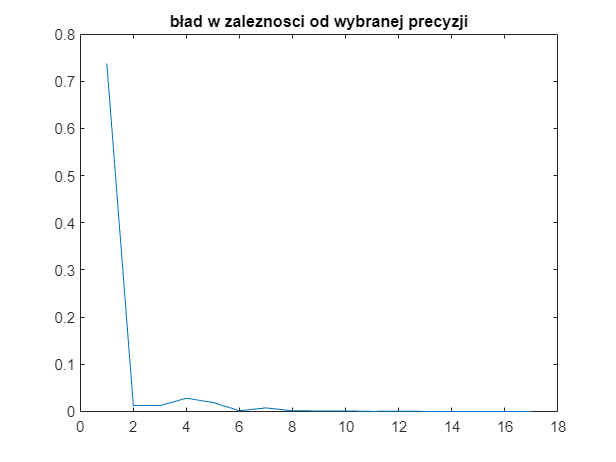

prec_f = 8

Y_fix =    -0.2633

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 16

ans = '111111011110010011001'

plot(res)
title("bład w zaleznosci od wybranej precyzji")